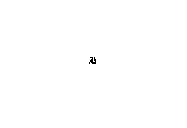

A = [1 0 0 0 1 0 1
     1 1 1 0 1 0 1
     1 1 0 0 1 0 0
     1 0 0 0 1 0 0
     1 0 0 0 1 1 0
     0 1 0 0 0 0 0
     0 1 1 0 0 0 0
     ];
 
B = bwskel(logical(A),"MinBranchLength",5);
imshow(A);

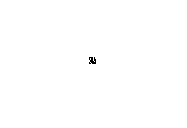

imshow(B);

## Testing on an image

original = imread('planes.png');

Error using imread>get_full_filename (line 567)
File "planes.png" does not exist.

Error in imread (line 374)
    fullname = get_full_filename(filename);

originalBW = im2bw(original,0.5);
%Create a flat, line-shaped structuring element.

se = strel('line',50,180);
%Erode the image with the structuring element.

erodedBW = imerode(originalBW,se);
%View the original image and the eroded image.

figure
imshow(originalBW)
figure
imshow(erodedBW)
skel = erodedBW;
for i = 1:1:10
    skel = imerode(erodedBW,se);
end

figure
imshow(skel)

## Somethin gcomoletely different


for i = 150:1:500
    fprintf("trying: %d",i)
    if mod(20289,i) == 0
        fprintf("\nFound: %d\n",i);
    end
end

fprintf("END")

## Testing Peppers

image_unresized = imread("peppers.png")

image_unresized = 384×512×3 uint8 array
image_unresized(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    

image = imresize(image_unresized,[120,160])

image = 120×160×3 uint8 array
image(:,:,1) =

    63    63    64    65    64    64    63    66    68    68    69    70    70    70    70    67    69    68    69    69    70    70    64    52    51    56    56    58    61    68    67    67    67    67    65    64    65    64    63    63    63    64    67    65    67    70    71    70    69    69    71    73    75    75    76    73    69    64    63    61    62    65    67    68    68    70    70    68    67    69    68    70    73    73    71    69    69    68    68    69    69    69    67    69    72    72    70    67    63    68    69    69    70    69    67    66    67    69    68    69    66    66    67    66    65    65    67    69    70    68    68    70    69    64    65    68    69    68    68    70    69    64    62    64    66    67    67    64    62    59    56    61    71    74    63    55    56    60    55    54    54    56    61    63    61    60    61    62    58    59    62    61    62    60    58    58    59    60    60

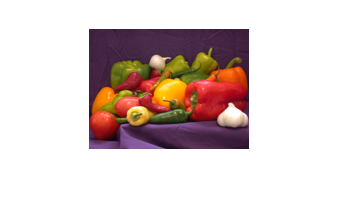


imshow(image)

threshold = graythresh(image)

threshold = 0.4588

BW_image = im2bw(image,threshold);

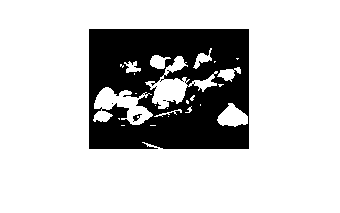

imshow(BW_image);

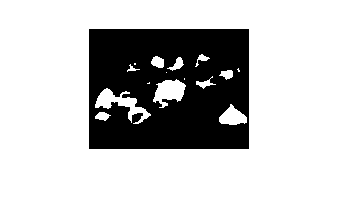


structuring_el = strel("square",3);

eroded_BW = imerode(BW_image,structuring_el);
imshow(eroded_BW);

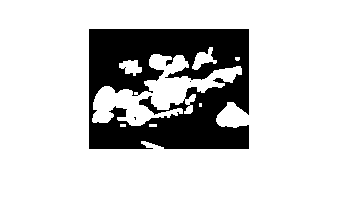

dilated_BW = imdilate(BW_image,structuring_el);
figure
imshow(dilated_BW)

% Comparing to our eroded 
diy_erode = imread("Eroded_1.bmp")

Error using imread>get_full_filename (line 567)
File "Eroded_1.bmp" does not exist.

Error in imread (line 374)
    fullname = get_full_filename(filename);

comparison = bitxor(diy_erode,im2uint8(eroded_BW))
imshow(comparison)

%Trying to get the same luminance values
image_greyscale = (0.299.*image(:,:,1)) + ...
                  (0.587.*image(:,:,2)) + ...
                  (0.114.*image(:,:,3));
new_threshold = graythresh(image_greyscale)

new_threshold = 0.3961

image_gs_BW = im2bw(image_greyscale,threshold)

image_gs_BW = 120×160 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

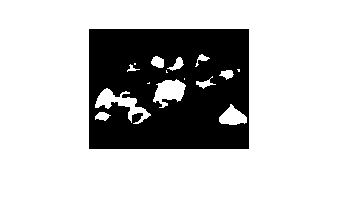

image_gs_BW_eroded = imerode(image_gs_BW,structuring_el);
figure
imshow(image_gs_BW_eroded)